clc; clear; close all;

% Parámetros
tolerancia_distancia = 1;
tolerancia_angulo = deg2rad(5);
avance_dist = 3;
giro_angulo = deg2rad(10);

% Punto objetivo en marco del origen (global)
punto_objetivo_global = [-3; -2];

% Posición y orientación inicial del marco móvil
pos_movil = [1; 3];
theta_movil = deg2rad(30);

% Figura
figure;
axis equal;
grid on;
hold on;
title(['Control a Obj=(',num2str(punto_objetivo_global(1)),',',num2str(punto_objetivo_global(2)),')']);
cont = 0

cont = 0

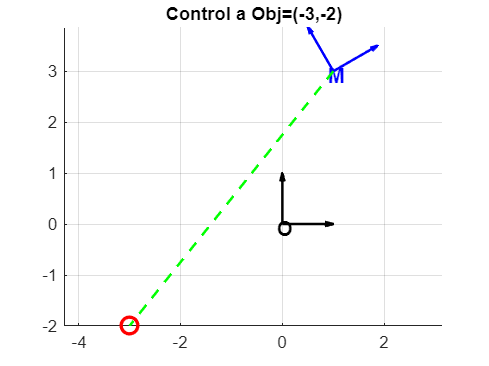

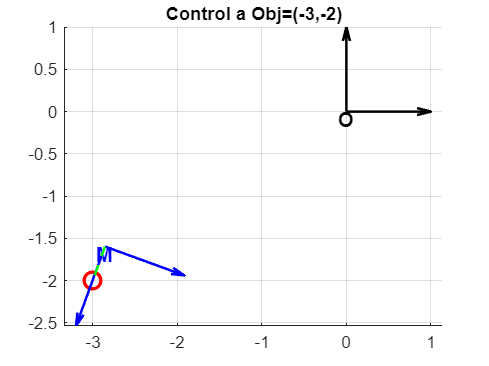

Objetivo alcanzado



% Función para dibujar un marco
function dibujar_marco(pos, theta, nombre, color)
    R = [cos(theta), -sin(theta); sin(theta), cos(theta)];
    origen = pos;
    x_axis = origen + R * [1; 0];
    y_axis = origen + R * [0; 1];
    quiver(origen(1), origen(2), x_axis(1)-origen(1), x_axis(2)-origen(2), 0, color, 'LineWidth', 1.5, 'MaxHeadSize', 0.5);
    quiver(origen(1), origen(2), y_axis(1)-origen(1), y_axis(2)-origen(2), 0, color, 'LineWidth', 1.5, 'MaxHeadSize', 0.5);
    text(origen(1)-0.1, origen(2)-0.1, nombre, 'Color', color, 'FontSize', 12, 'FontWeight', 'bold');
end

while true && cont < 100
    cla;
    % Dibujar marco origen y objetivo
    dibujar_marco([0; 0], 0, 'O', 'k');
    plot(punto_objetivo_global(1), punto_objetivo_global(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);

    % Transformar punto objetivo al marco móvil
    R_movil = [cos(theta_movil), -sin(theta_movil); sin(theta_movil), cos(theta_movil)];
    punto_local = R_movil' * (punto_objetivo_global - pos_movil);
    
    % Calcular distancia y ángulo al objetivo en marco local
    distancia = norm(punto_local);
    angulo = atan2(punto_local(2), punto_local(1));

    % Dibujar marco móvil y línea al objetivo
    dibujar_marco(pos_movil, theta_movil, 'M', 'b');
    plot([pos_movil(1), punto_objetivo_global(1)], [pos_movil(2), punto_objetivo_global(2)], 'g--', 'LineWidth', 1.5);

    % Lógica de control
    if abs(angulo) > tolerancia_angulo
        % Corregir orientación
        if angulo > 0
            theta_movil = theta_movil + giro_angulo;
        else
            theta_movil = theta_movil - giro_angulo;
        end
    elseif distancia > tolerancia_distancia
        % Avanzar si ya está bien orientado
        pos_movil = pos_movil + R_movil * [avance_dist; 0];
    else
        % Objetivo alcanzado
        disp('Objetivo alcanzado');
        break;
    end
    pause(0.1);
end